# 02 Homework: Continuous Problems

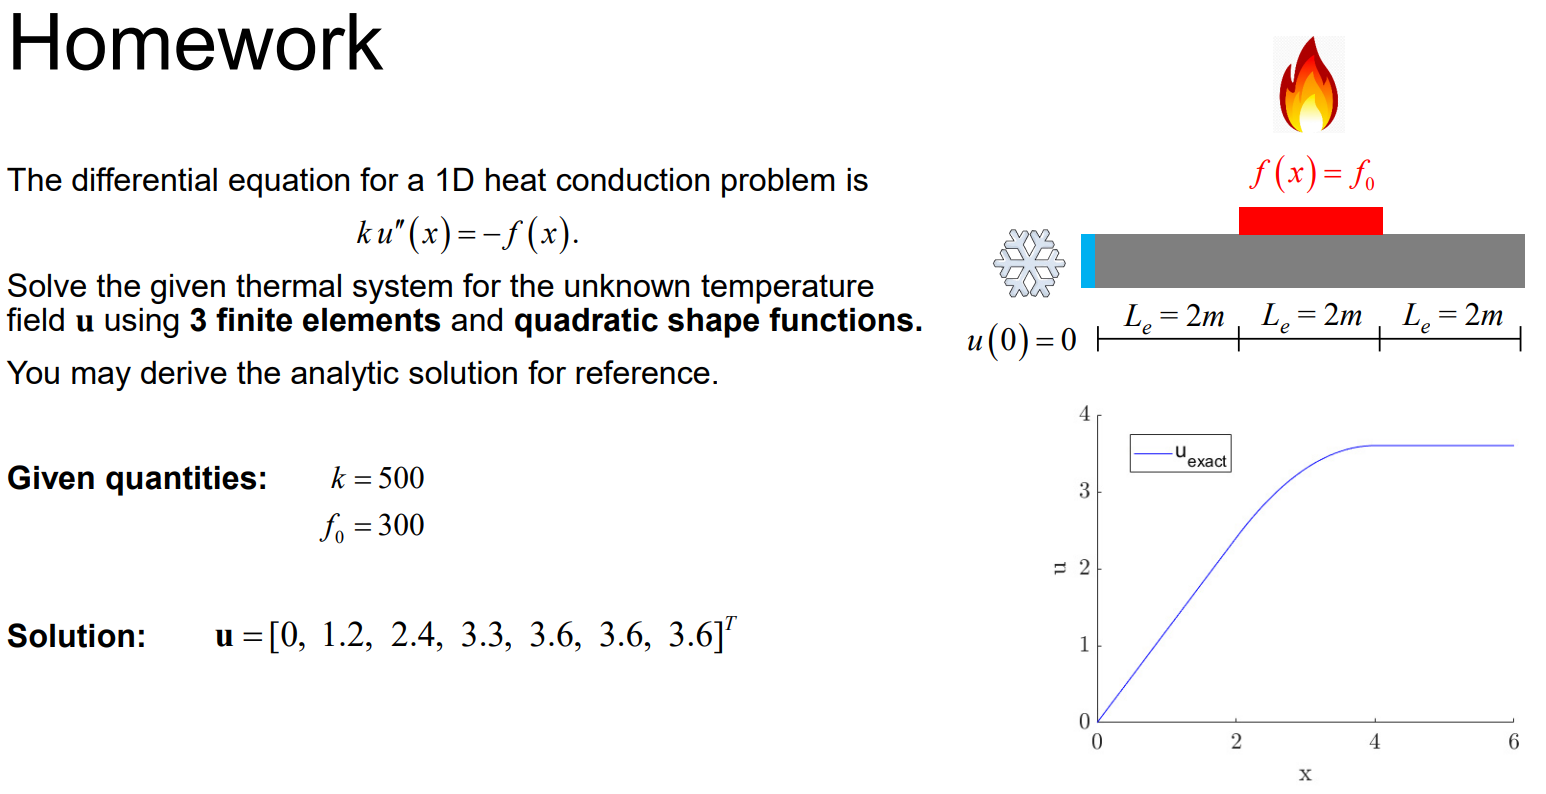

clc; clear all; close all;

k  = 500;
f0 = 300;

nNodes      = 7;
nodes       = linspace(0, 6, nNodes);
nElements   = 3;

% Set up Elements
elements    = [1, 2, 3;
               3, 4, 5;
               5, 6, 7];

nodesPerElement = 3;
dofPerElement   = nodesPerElement;
degree          = 2;

% Line load per element
f0FEMquad = [0; f0; 0];

% Initialize global system
Kq = zeros(nNodes);
uq = zeros(nNodes, 1);
fq = zeros(nNodes, 1);

% Assemble stiffness matrix and load vector
for e = 1 : nElements
    KE = zeros(3);
    fE = zeros(3, 1);

    firstNode = nodes(elements(e, 1));
    lastNode = nodes(elements(e, end));

    for j = 1 : dofPerElement
        for i = j : dofPerElement
            
            intK = @(x) k * shapeFunctions(x, firstNode, lastNode, i, 1, degree) .* ...
                            shapeFunctions(x, firstNode, lastNode, j, 1, degree);

            KE(i, j) = integral(intK, firstNode, lastNode);
            KE(j, i) = KE(i, j);

        end

        intF = @(x) f0FEMquad(e) * shapeFunctions(x, firstNode, lastNode, j, 0, degree);
        fE(j) = integral(intF, firstNode, lastNode);
    
    end

    indices = elements(e, :);
    Kq(indices, indices)    = Kq(indices, indices)  + KE;
    fq(indices)             = fq(indices)           + fE;

end

uq(2 : end) = Kq(2:end, 2:end) \ fq(2:end)

uq =          0
    1.2000
    2.4000
    3.3000
    3.6000
    3.6000
    3.6000


## Additional functions

function h = shapeFunctions(x, firstNode, lastNode, index, derivative, degree)
    % Evaluate and return shape function or derivative for 1D element
    % INPUT
    %   x (array)               Positions for evaluation of shape functions inside element
    %   firstNode (scalar)      Coordinate of first node for element
    %   lastNode (scalar)       Coordinate of last node for element
    %   index   (scalar/array)  Index or indices for shape functions to be returned
    %   derivative (bool)       Switch to return derivatives
    %   degree (scalar)         Degree for shape functions (1/2)
    % OUTPUT
    %   h (scalar/array)        Evaluation of shape functions or derivatives for given input x and index
    
    r = 2 * (x - firstNode) / (lastNode - firstNode) - 1;
    drdx = 2 / (lastNode - firstNode);
    switch degree
        case 1
            if derivative
                h = [-1/2 * ones(size(x));
                    1/2 * ones(size(x))] * drdx;
            else
                h = [(1 - r) ./ 2;
                     (1 + r) ./ 2];
            end
        case 2
            if derivative
                h = [- 1 / 2 + r;
                     - 2 * r;
                       1 / 2 + r] .* drdx;
            else
                h = [(1 - r)./2 - (1 - r.^2) ./ 2;
                      1 - r.^2;
                     (1 + r) ./ 2 - (1 - r.^2) ./ 2];
            end
        otherwise
            error('Shape function not implemented')
    end
    h = h(index, :);
end